# Resident Intruder Analysis

Load your behavior xcel as a table- change table labels to all caps

thisSheet=ls('*.xlsx');
hh=size(thisSheet)
if hh(1)>1
    for ii=1:2
        beh1=readtable(strtrim(thisSheet(1,1:end)));
        beh2=readtable(strtrim(thisSheet(2,1:end)));
        beh1.Properties.VariableNames{1}='Behavior';
        beh2.Properties.VariableNames{1}='Behavior';
        Behavior=vertcat(beh1,beh2);
        Behavior.Properties.VariableNames{2} = 'START';
        Behavior.Properties.VariableNames{3} = 'END';
            
    end
else
    Behavior=readtable(strtrim(thisSheet(1,1:end)));
    Behavior.Properties.VariableNames{2} = 'START';
    Behavior.Properties.VariableNames{3} = 'END';
end

%%load video timestamps
ReadVidTimeStamps
fps=15; %%frames per second

lightOn_inds=find(meanGrayLevels>mean(meanGrayLevels)+2*std(meanGrayLevels))/fps;

%%load Events
[Events.Ids, Events.timestamps, ~]=load_open_ephys_data_faster('all_channels.events');
[~, LFPtimestamps, ~]=load_open_ephys_data('101_CH1.continuous');
sampRate=30000;
Events.timestamps=Events.timestamps-LFPtimestamps(1);
save('Events','Events')

Behavior.START=Behavior.START(:)-lightOn_inds(1);
Behavior.END=Behavior.END(:)-lightOn_inds(1);
save('Behavior.mat','Behavior') 

parse behavior

Behavior.Behavior=string(Behavior.Behavior);
save('Behavior','Behavior')
nothing_inds=Behavior.Behavior=="nothing";
immobile_inds=Behavior.Behavior=="not moving";
walking_inds=Behavior.Behavior=="walking";
explore_inds=Behavior.Behavior=="SE";
dom_inds=Behavior.Behavior=="SD";
aggress_inds=Behavior.Behavior=="SA";

%set range

range=2;

Import Spike Data

TTs=ls('Binaries*'); sizeTTs=size(TTs);

for jj=1:sizeTTs(1)
    thisTT=TTs(jj,1:end);
    cd(thisTT)
    
    spikeStruct = loadKSdir(pwd);
    numClust=length(spikeStruct.cids);
    
    
    for ii=1:numClust
        if spikeStruct.cgs(1,ii)==2
            thisClust=spikeStruct.cids(ii);
            spikeInds=find(spikeStruct.clu==thisClust);
            st=spikeStruct.st(spikeInds);
            thesespikeTimes=find(st>Events.timestamps(1) & st<Events.timestamps(end));
            spike_Times=st(thesespikeTimes)-Events.timestamps(1);
            spikeTimes{ii,jj}=spike_Times;
            
        end
    end
    clear spikeStruct
    cd ..
    
end
R.Spike.t=spikeTimes;
save('R','R')


%%make dirs for each TT

numTetrodes=size(R.Spike.t);
for Tetrode=1:numTetrodes(2)
    for Unit=1:numTetrodes(1)
        if isempty(R.Spike.t{Unit,Tetrode})
        else
            tetrode=num2str(Tetrode);
            tetrode=strcat('TT',tetrode);
            unit=num2str(Unit);
            unit=strcat('unit',unit);
            Tetrodecell=strcat(tetrode,unit);
            mkdir(Tetrodecell);cd (Tetrodecell)
            spikeTimes=R.Spike.t{Unit,Tetrode};
            thesespikeTimes=find(spikeTimes>Events.timestamps(1) & spikeTimes<Events.timestamps(end));
            spikeTimes=spikeTimes(thesespikeTimes)-Events.timestamps(1);
            save('spikeTimes','spikeTimes');clear spikeTimes
            cd ..
        end
    end
end



ss=1;

makeEvsMatrix_ss

save('evs_matrix.mat','evs_matrix_ss')

%%make labels vector
Aggress_start=Behavior.START(aggress_inds==1);
Aggress_end=Behavior.END(aggress_inds==1);

for ii=1:length(Aggress_start)
    AggressPosInds{ii}=find(R.Pos.t>(Aggress_start(ii))&R.Pos.t<(Aggress_end(ii)));
end

SD_start=Behavior.START(dom_inds==1);
SD_end=Behavior.END(dom_inds==1);

for ii=1:length(SD_start)
    SDPosInds{ii}=find(R.Pos.t>(SD_start(ii))&R.Pos.t<(SD_end(ii)));
end

SE_start=Behavior.START(explore_inds==1);
SE_end=Behavior.END(explore_inds==1);

for ii=1:length(SE_start)
    SEPosInds{ii}=find(R.Pos.t>(SE_start(ii))&R.Pos.t<(SE_end(ii)));
end


%%non social stuff
not_moving_start=Behavior.START(immobile_inds==1);
not_moving_end=Behavior.END(immobile_inds==1);

for ii=1:length(not_moving_start)
    not_moving_PosInds{ii}=find(R.Pos.t>(not_moving_start(ii))&R.Pos.t<(not_moving_end(ii)));
end

walking_start=Behavior.START(walking_inds==1);
walking_end=Behavior.END(walking_inds==1);

for ii=1:length(walking_start)
    WalkingPosInds{ii}=find(R.Pos.t>(walking_start(ii))&R.Pos.t<(walking_end(ii)));
end



LabelVector=zeros(1,length(R.Pos.t));
if ~isempty(not_moving_end)
    for ii=1:length(not_moving_PosInds)
        LabelVector(not_moving_PosInds{ii})=1;
    end
end
if ~isempty(walking_end)
    for ii=1:length(WalkingPosInds)
        LabelVector(WalkingPosInds{ii})=2;
    end
end

if ~isempty(Aggress_end)
for ii=1:length(AggressPosInds)
    LabelVector(AggressPosInds{ii})=3;
end
end

for ii=1:length(SEPosInds)
    LabelVector(SEPosInds{ii})=4;
end
if ~isempty(SD_end)
    for ii=1:length(SDPosInds)
        LabelVector(SDPosInds{ii})=5;
    end
end
save('LabelVector','LabelVector')
plot(LabelVector,'k','LineWidth',2)

evs_matrix=evs_matrix_ss;
plot(sum(evs_matrix(:,2:end-1))); hold on
filterWidth=30;
filteredFR=filterGauss(sum(evs_matrix(:,2:end-1)),filterWidth);
plot(filteredFR,'k','LineWidth',3); hold off

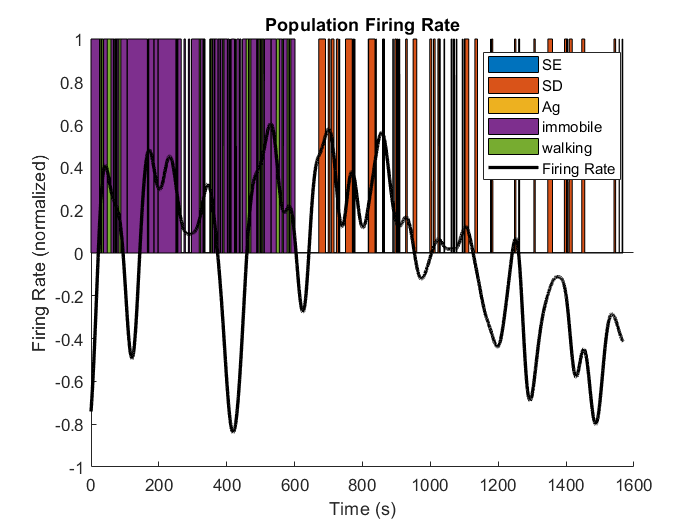


%plot(smooth(sum(evs_matrix(:,2:end-1)))); hold on
hold off

filterWidth=250;
filteredFR=filterGauss(zscore(sum(evs_matrix(:,2:end-1))),filterWidth);hold on


SEon=zeros(1,length(R.Pos.t));
    SEon(LabelVector==4)=1;
area(R.Pos.t(2:end-1),SEon(2:end-1))

SDon=zeros(1,length(R.Pos.t));
    SDon(LabelVector==5)=1;
area(R.Pos.t(2:end-1),SEon(2:end-1))

aggresson=zeros(1,length(R.Pos.t));
    aggresson(LabelVector==3)=1;
area(R.Pos.t(2:end-1),aggresson(2:end-1))

immobile_on=zeros(1,length(R.Pos.t));
    immobile_on(LabelVector==1)=1;
area(R.Pos.t(2:end-1),immobile_on(2:end-1))

walking_on=zeros(1,length(R.Pos.t));
    walking_on(LabelVector==2)=1;
area(R.Pos.t(2:end-1),walking_on(2:end-1))

plot(R.Pos.t(2:end-1),filteredFR,'k','LineWidth',2)


legend({'SE','SD','Ag','immobile','walking','Firing Rate'})

xlabel('Time (s)')
ylabel('Firing Rate (normalized)')
title('Population Firing Rate')

hold off

sizeEvents=size(evs_matrix);
filterWidth=100;
for uu=1:sizeEvents(1)
    theseSpikes=evs_matrix(uu,:);
    theseSpikes=zscore(theseSpikes);
    theseSpikes_smooth(uu,:)=filterGauss(theseSpikes,filterWidth);
    figure(uu);hold on
    area(R.Pos.t(2:end-1),SEon(2:end-1));area(R.Pos.t(2:end-1),aggresson(2:end-1));area(R.Pos.t(2:end-1),SDon(2:end-1))
    %plot(R.Pos.t,theseSpikes,'color',[ 0.5 0.5 0.5])
    plot(R.Pos.t,theseSpikes_smooth(uu,:),'k','linewidth',2)
    legend({'SE','Aggression','SD','FiringRate'})
    xlabel('Time(s)')
    ylabel('Firing Rate (normalized)')
    cellNum=num2str(uu); 
    Title=strcat('cell ',cellNum); 

    title(Title)
    hold off
end

Train SVM Social vs NonSocial

## train on the resident intruder part of the task only, training with the habituation classifies everything as zeros

For NLX data only:

evs_matrix_ss=evs_matrix(:,Events_TimeStamps(4)*29.97:Events_TimeStamps(5)*29.97);
LabelVector=LabelVector(:,Events_TimeStamps(4)*29.97:Events_TimeStamps(5)*29.97);



   Mdl=fitcecoc(evs_matrix',LabelVector')

Mdl =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4]
           ScoreTransform: 'none'
           BinaryLearners: {10×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


   
CVSVMModel = crossval(Mdl);
classLoss = kfoldLoss(CVSVMModel)

classLoss = 0.4508

isLoss=resubLoss(Mdl)

isLoss = 0.4440

[Mdl_labels,scores]=predict(Mdl,evs_matrix_ss');

PredictCorrect=find(Mdl_labels==LabelVector');
percentCorrect=length(PredictCorrect)/length(LabelVector)

percentCorrect = 0.5560

Shuffle your data   

evs_matrix=evs_matrix_ss;
evs_matrix_sh=evs_matrix(:,randperm(size(evs_matrix,2)));

%Mdl_sh=fitcecoc(evs_matrix_sh',LabelVector_sh')

[chance_labels,scores]=predict(Mdl,evs_matrix_sh');

PredictCorrect_sh=find(chance_labels==LabelVector');
percentCorrect_sh=length(PredictCorrect_sh)/length(LabelVector)

numChunks=5;%% numChunks is crossval
for i=1:max(LabelVector)
    for j=1:max(LabelVector)
        [CorrectTrain{i,j},CorrectTest{i,j}]=DecodeInteraction(evs_matrix_ss(:,LabelVector==i),evs_matrix_ss(:,LabelVector==j),LabelVector(:,LabelVector==i),LabelVector(:,LabelVector==j),numChunks,0);
        [~,CorrectTest_sh{i,j}]=DecodeInteraction(evs_matrix_sh(:,LabelVector==i),evs_matrix_sh(:,LabelVector==j),LabelVector(:,LabelVector==i),LabelVector(:,LabelVector==j),numChunks,0);

    end
end

numChunks=5;%% numChunks is crossval
for i=1:max(LabelVector)
    for j=1:max(LabelVector)
        [~,CorrectTest_sh{i,j}]=DecodeInteraction(evs_matrix_sh(:,LabelVector==i),evs_matrix_sh(:,LabelVector==j),LabelVector(:,LabelVector==i),LabelVector(:,LabelVector==j),numChunks,0);
    end
end

for ii=1:length(CT)
    test(:,ii)=reshape(CT{ii}{2,1},[],1);
end

test(test==0)=NaN;

for ii=1:length(CT)
    test_sh(:,ii)=reshape(CT_sh{ii}{2,1},[],1);
end

test_sh(test_sh==0)=NaN;

Train SVM for SE vs SD vs Aggression

Find spikes that happened during aggression


Aggress_start=Behavior.START(aggress_inds==1);
Aggress_end=Behavior.END(aggress_inds==1);

list_cells=num2str(ls('TT*unit*'));

for jj=1:length(list_cells)
    for ii=1:length(Aggress_start)
        thisCell=list_cells(jj,1:9);
        cd(thisCell);
        load('spikeTimes.mat')
        Aggress_spikes_inds{ii}= find(spikeTimes>(Aggress_start(ii)-2)&spikeTimes<(Aggress_start(ii)+2));
        Aggress_spikes{jj,ii}=spikeTimes(Aggress_spikes_inds{ii});
        cd ..
    end
end

dom_start=Behavior.START(dom_inds==1);
dom_end=Behavior.END(dom_inds==1);

list_cells=num2str(ls('TT*unit*'));

for jj=1:length(list_cells)
    for ii=1:length(dom_start)
        thisCell=list_cells(jj,1:9);
        cd(thisCell);
        load('spikeTimes.mat')
        Dom_spikes_inds{ii}= find(spikeTimes>(dom_start(ii)-range)&spikeTimes<(dom_start(ii)+range));
        Dom_spikes{jj,ii}=spikeTimes(Dom_spikes_inds{ii});
        cd ..
    end
end


explore_start=Behavior.START(explore_inds==1);
explore_end=Behavior.END(explore_inds==1);

list_cells=num2str(ls('TT*unit*'));

for jj=1:length(list_cells)
    for ii=1:length(explore_start)
        thisCell=list_cells(jj,1:9);
        cd(thisCell);
        load('spikeTimes.mat')
        Explore_spikes_inds{ii}=find(spikeTimes>(explore_start(ii)-2)&spikeTimes<(explore_start(ii)+2));
        Explore_spikes{jj,ii}=spikeTimes(Explore_spikes_inds{ii});
        cd ..
    end
end

%load('R.mat');load('evs_matrix.mat')
%plot(smooth(sum(evs_matrix(:,2:end-1)))); hold on
filterWidth=50;
filteredFR=filterGauss(sum(evs_matrix(:,2:end-1)),filterWidth);hold on
plot(filteredFR,'k','LineWidth',2)
aggresson=zeros(1,length(R.Pos.t));
for kk=1:length(Aggress_spikes_inds)
    aggresson(Aggress_spikes_inds{kk})=8;
end
plot(1:length(aggresson)-2,aggresson(2:end-1),'r','LineWidth',2)
% SDon=zeros(1,length(R.Pos.t));
% for mm=1:length(Dom_spikes_inds)
%     SDon(Dom_spikes_inds{mm})=8;
% end
% plot(1:length(SDon)-2,SDon(2:end-1),'y','LineWidth',2)

SEon=zeros(1,length(R.Pos.t));
for rr=1:length(Explore_spikes_inds)
    SEon(Explore_spikes_inds{rr})=8;
end
plot(1:length(SEon)-2,SEon(2:end-1),'b','LineWidth',2)

Find spikes that happened during Social Exploration

Plot rasters for Aggress times

for ii=1:length(list_cells)
    figure(ii);thisCell=list_cells(ii,1:9);cd(thisCell);
    for tr = 1:length(Aggress_start)
        if isempty(Aggress_spikes{ii,tr})
        else
            spikesT = Aggress_spikes{ii,tr}-Aggress_spikes{ii,tr}(1,1);
            TrialLength=2;
            yVals = tr + 0*spikesT;  % offset by one vertically for each trial
            markerSize=12;
            
            plot(spikesT, yVals, 'g', 'markerSize', markerSize);
            hold on
            ylim([0 length(Aggress_start)+1])
            title(strcat(thisCell,'Aggression'))
        end
        
    end
    savefig(strcat(thisCell,'Aggression'))
    cd ..
    hold off
end

Plot Firing Rates

hold off

list_cells=num2str(ls('TT*unit*'));

for ii=1:length(list_cells)
    figure(ii);
    thisCell=list_cells(ii,1:9);cd(thisCell);
    numtargetSpikes={};
    for tr = 1:length(Aggress_start)
        binsize=.10; %binsize in ms
        range=2; %amount of time before and after aggressive episode
        % TARG LOCKED
        targetLockedTimes = Aggress_start(tr)-range:binsize:Aggress_start(tr)+range;  % range of times we are using
        for kk=2:length(targetLockedTimes)
            targetSpikesInd{tr,kk}=find(Aggress_spikes{ii,tr}>targetLockedTimes(kk-1)&Aggress_spikes{ii,tr}<targetLockedTimes(kk));
            numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk})*10;
        end
    end
    numtargetSpikes=(cell2mat(numtargetSpikes))*binsize;
    % plotting
    filterWidth=2;
    figure (ii); hold on;
    %plot(targetLockedTimes(2:end), mean(numtargetSpikes), 'r');hold on;
    rate = filterGauss(mean(numtargetSpikes), filterWidth);
    ax1=subplot(1,3,1);
    plot(targetLockedTimes(2:end), rate, 'r', 'linewidth', 3); hold on
    xx=targetLockedTimes(21);
    line([xx xx],[0 max(rate)],'LineWidth',2,'Color','black')
    cellNum=num2str(ii);Title=(strcat('Aggression-cell',cellNum));
    title(Title)
    ylabel('Firing Rate')
    set(gca,'xtick',[])
    
    clear -numTargetSpikes targetLockedTimes rate Title xx 
    numtargetSpikes={};
    for tr = 1:length(explore_start)
        binsize=.1; %binsize in ms
        
        % TARG LOCKED
        targetLockedTimes = explore_start(tr)-range:binsize:explore_start(tr)+range;  % range of times we are using
        for kk=2:length(targetLockedTimes)
            targetSpikesInd{tr,kk}=find(Explore_spikes{ii,tr}>targetLockedTimes(kk-1)&Explore_spikes{ii,tr}<targetLockedTimes(kk));
            numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk})*10;
        end
    end
    numtargetSpikes=(cell2mat(numtargetSpikes))*binsize;
    % plotting
    filterWidth=2;
    figure (ii); hold on;
    rate = filterGauss(mean(numtargetSpikes), filterWidth);
    ax2=subplot(1,3,2);
    plot(targetLockedTimes(2:end), rate, 'b', 'linewidth', 3); hold on
    xx=targetLockedTimes(21);
    line([xx xx],[0 max(rate)],'LineWidth',2,'Color','black');hold off;
    Title=(strcat('SE-cell',cellNum));
    title(Title)
    set(gca,'xtick',[])
    
%         clear -numTargetSpikes targetLockedTimes rate Title xx 
%     numtargetSpikes={};
%         for tr = 1:length(dom_start)
%         binsize=.1; %binsize in ms
%         
        % TARG LOCKED
%         targetLockedTimes = dom_start(tr)-range:binsize:dom_start(tr)+range;  % range of times we are using
%         for kk=2:length(targetLockedTimes)
%             targetSpikesInd{tr,kk}=find(Dom_spikes{ii,tr}>targetLockedTimes(kk-1)&Dom_spikes{ii,tr}<targetLockedTimes(kk));
%             numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk})*10;
%         end
%     end
%     numtargetSpikes=(cell2mat(numtargetSpikes))*binsize;
%     % plotting
%     filterWidth=2;
%     figure (ii); hold on;
%     rate = filterGauss(mean(numtargetSpikes), filterWidth);
%     ax3=subplot(1,3,3);
%     plot(targetLockedTimes(2:end), rate, 'color',[1 0.7 0], 'linewidth', 3);hold on;
%     xx=targetLockedTimes(21);
%     line([xx xx],[0 max(rate)],'LineWidth',2,'Color','black'); hold off
%     Title=(strcat('SD-cell',cellNum));
%     title(Title)
    linkaxes([ax1 ax2 ax2],'y')
    set(gca,'xtick',[])
    
    hold off
    cd ..
    
end




for ii=1:length(list_cells)
    figure(ii);thisCell=list_cells(ii,1:9);
    numtargetSpikes={};
    for tr = 1:length(explore_start)
        binsize=.1; %binsize in ms
        
        % TARG LOCKED
        targetLockedTimes = explore_start(tr)-range:binsize:explore_start(tr)+range;  % range of times we are using
        for kk=2:length(targetLockedTimes)
            targetSpikesInd{tr,kk}=find(Explore_spikes{ii,tr}>targetLockedTimes(kk-1)&Explore_spikes{ii,tr}<targetLockedTimes(kk));
            numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk});
        end
    end
    numtargetSpikes=(cell2mat(numtargetSpikes))*binsize;
    % plotting
    filterWidth=2;
    figure (ii); hold on;
    plot(targetLockedTimes(2:end), mean(numtargetSpikes), 'g');hold on;
    rate = filterGauss(mean(numtargetSpikes), filterWidth);
    plot(targetLockedTimes(2:end), rate, 'k', 'linewidth', 3);hold off;
    
    cd(thisCell);
    savefig(strcat(thisCell,'ExploreFR'))
    cd ..
    
end

for ii=1:length(list_cells)
    figure(ii);thisCell=list_cells(ii,1:9);
    numtargetSpikes={};
    for tr = 1:length(dom_start)
        binsize=.05; %binsize in ms
        
        % TARG LOCKED
        targetLockedTimes = dom_start(tr)-range:binsize:dom_start(tr)+range;  % range of times we are using
        for kk=2:length(targetLockedTimes)
            targetSpikesInd{tr,kk}=find(Dom_spikes{ii,tr}>targetLockedTimes(kk-1)&Dom_spikes{ii,tr}<targetLockedTimes(kk));
            numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk});
        end
    end
    numtargetSpikes=(cell2mat(numtargetSpikes))*binsize;
    % plotting
    filterWidth=2;
    figure (ii); hold on;
    plot(targetLockedTimes(2:end), mean(numtargetSpikes), 'b');hold on;
    rate = filterGauss(mean(numtargetSpikes), filterWidth);
    plot(targetLockedTimes(2:end), rate, 'k', 'linewidth', 3);hold off;
    
    cd(thisCell);
    savefig(strcat(thisCell,'DomFR'))
    cd ..
    
end

Look at Correlations between cells during certain behavior?

for ii=1:length(list_cells)-1
    numtargetSpikes={};
    for tr = 1:length(dom_start)
        binsize=.05; %binsize in ms
        
        % TARG LOCKED
        targetLockedTimes = dom_start(tr)-range:binsize:dom_start(tr)+range;  % range of times we are using
        for kk=2:length(targetLockedTimes)
            targetSpikesInd{tr,kk}=find(Dom_spikes{ii,tr}>targetLockedTimes(kk-1)&Dom_spikes{ii,tr}<targetLockedTimes(kk));
            numtargetSpikes{tr,kk}=length(targetSpikesInd{tr,kk});
        end
    end
    %r(ii)=
end

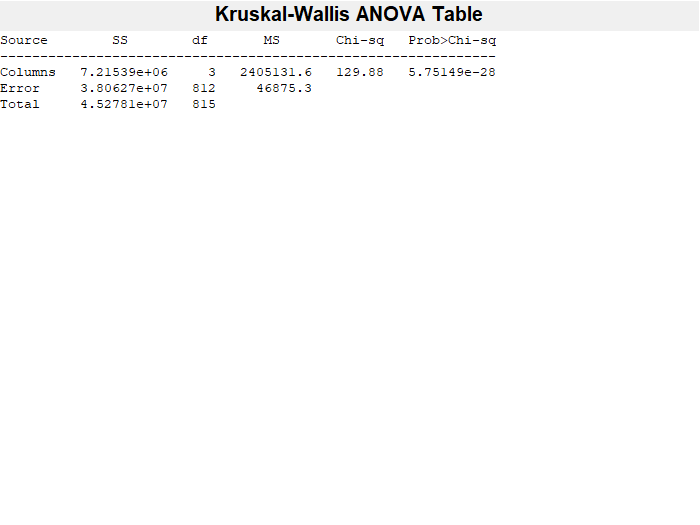

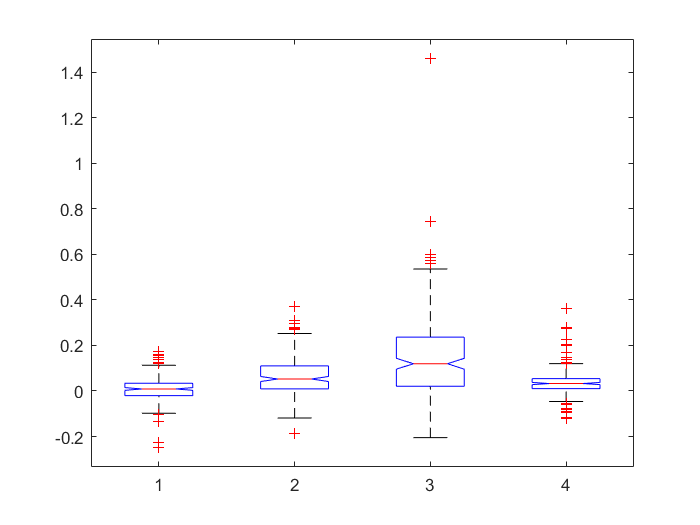

ans = 5.7515e-28

evs_matrix_norm=zscore(evs_matrix')';


    for ii=1:max(LabelVector)
        these_evs_norm=evs_matrix_norm(:,find(LabelVector==ii));
        mean_activity(:,ii)=mean(these_evs_norm');
    end


kruskalwallis(mean_activity)